# Q2

#### (a)

see the tail of the file for the function.

routine:

- generate the companion matrix (using `get_companion_matrix`) given all coefficients (from lower power to higher power)

- find all eigenvalues of the matrix (using `eig`), they are the roots of the polynomial

#### (b)

cs = [24, -40, 35, -13, 2, 0, 0, 5, -2, 10];

A = get_companion_matrix(cs)

A =      0     0     0     0     0     0     0     0     0   -24
     1     0     0     0     0     0     0     0     0    40
     0     1     0     0     0     0     0     0     0   -35
     0     0     1     0     0     0     0     0     0    13
     0     0     0     1     0     0     0     0     0    -2
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0    -5
     0     0     0     0     0     0     0     1     0     2
     0     0     0     0     0     0     0     0     1   -10


rts = eig(A);

disp("Roots:")

Roots:


disp(rts)

  -1.3377 + 0.0000i
  -0.7824 + 1.0246i
  -0.7824 - 1.0246i
   0.1364 + 1.1484i
   0.1364 - 1.1484i
   0.8743 + 0.3274i
   0.8743 - 0.3274i
   0.5620 + 0.7670i
   0.5620 - 0.7670i
 -10.2429 + 0.0000i




% verify
p = @(t) 24-40*t+35*t.^2-13*t.^3+2*t.^4+5*t.^7 ...
    -2*t.^8+10*t.^9+t.^10;
p(rts)

ans = 1.0e-11 *

  -0.2071 + 0.0000i
   0.0163 - 0.0149i
   0.0163 + 0.0149i
  -0.0100 - 0.0034i
  -0.0100 + 0.0034i
  -0.0072 + 0.0054i
  -0.0072 - 0.0054i
  -0.0081 + 0.0053i
  -0.0081 - 0.0053i
   0.0000 + 0.0000i



% check
disp("Roots given by in-built function:")

Roots given by in-built function:


roots(flip([cs 1]))

ans =  -10.2429 + 0.0000i
  -1.3377 + 0.0000i
  -0.7824 + 1.0246i
  -0.7824 - 1.0246i
   0.1364 + 1.1484i
   0.1364 - 1.1484i
   0.5620 + 0.7670i
   0.5620 - 0.7670i
   0.8743 + 0.3274i
   0.8743 - 0.3274i


#### (c) Spectral radius

disp(max(abs(rts)))

   10.2429



# Q3

A = [
 [6, 2, 1];
 [2, 3, 1];
 [3, 1, -1]
]

A =      6     2     1
     2     3     1
     3     1    -1


X0 = eye(3, 3);

#### (c)

[Q, R, B, T] = orthogit(A, X0, 100)

Q =    -0.8268    0.4298   -0.3629
   -0.4447   -0.8945   -0.0462
   -0.3444    0.1232    0.9307


R =     7.4924   -0.0923    1.7889
         0    1.9471   -0.8895
         0         0   -1.4395


B =     7.4924   -0.0923    1.7889
    0.0000    1.9471   -0.8895
    0.0000   -0.0000   -1.4395


T =     1.0000    1.0000    1.0000
   -7.0000   -2.2361   -1.3416
    7.2548    1.9000   -1.5235
    7.5172    2.0007   -1.3963
    7.4879    1.9058   -1.4716
    7.4936    1.9770   -1.4175
    7.4923    1.9245   -1.4564
    7.4925    1.9635   -1.4274
    7.4924    1.9348   -1.4486
    7.4924    1.9561   -1.4329


disp("Eiegnvalues:")

Eiegnvalues:


evs = diag(B)

evs =     7.4924
    1.9471
   -1.4395


disp(evs)

    7.4924
    1.9471
   -1.4395



disp("First two eigenvectors:")

First two eigenvectors:


disp(Q(:, 1))

   -0.8268
   -0.4447
   -0.3444



disp(Q(:, 2))

    0.4298
   -0.8945
    0.1232



rate of convergence

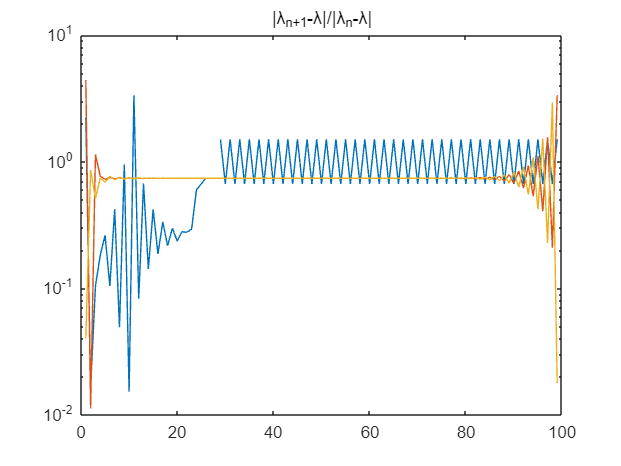

figure
semilogy(abs(T(2:end, 1) - evs(1))./ abs(T(1:end-1, 1) -  evs(1)))
hold on
semilogy(abs(T(2:end, 2) - evs(2))./ abs(T(1:end-1, 2) -  evs(2)))
semilogy(abs(T(2:end, 3) - evs(3))./ abs(T(1:end-1, 3) -  evs(3)))
title("|λ_{n+1}-λ|/|λ_{n}-λ|")
hold off

Hence it converges linearly.

# Q4

H = hilb(15);
H

#### (a) 20 iterations needed

format long
[eigenvals1, iters] = qr_shift(H, 1000, 1e-16)

#### (b) 14 iterations needed, 6 iteration less than (a). Got the same eigenvalues (but of different order) as in (a)

format long
[B, ~] = hessenberg(H)
[eigenvals2, iters] = qr_shift(B, 1000, 1e-16)

relative error

norm(sort(eigenvals1) - sort(eigenvals2)) / norm(eigenvals1)

# Q5

A = [
  [2, 3, 5, 6];
  [3, -1, -2, -3];
  [5, -2, 0, 2];
  [6, -3, 2, 22]
]
x0 = [1, 1, 1, 1]';

Power iteration

ref = eigs(A)
disp("Ref max eigenvalue:")
disp(ref(1))

[val, vec, errs] = power_iteration(A, x0, 1e-6, 1000, ref(1));

disp("Eigenvalue:")
disp(val)
disp("Eigenvector:")
disp(vec)
disp("Absolute Errors:")
disp(errs)

figure;
semilogy(errs)
title("Errors")

Hence the convergence is **linear. **The estimate number of iterations is $-\log 10^{-6}=6$, which is exactly the same as the actual number.

# Functions

function A = get_companion_matrix(cs)
    n = length(cs);
    A = zeros(n, n);

    A(2:end, 1:end-1) = eye(n-1);
    A(:, n) = -cs';
end

function [val, vec, err] = power_iteration(A, x0, tol, max_iter, ref) 
    vec = x0 / norm(x0);
    i = 0;
    val = norm(A * vec);
    err = [];
    while i < max_iter
        vec = A * vec;
        vec = vec / norm(vec);
        val = norm(A * vec);

        err = [err; abs(val - ref)];

        if err(end) < tol
            break;
        end
    end
end

function [Q,R,B,T] = orthogit(A,X0,maxit)
    % orthogonal iterations for the p eigenvalues of A
    % X0 - n x p initial matrix
    % Q - n x p left-orthogonal matrix
    % R - p x p upper-triangular matrix with positive diagonal coefficients
    % B - p x p block-triangular matrix
    X = X0;
    Z = eye(length(A(:, 1)));
    T = [];
    for i = 1:maxit
        [Q,R] = qr(X);
        T = [T;diag(R)'];
        X = A*Q;
    end
    B = Q'*A*Q;
end

Given

function [lambdas step] = qr_shift(A, max_iter, tol)
  [n n] = size(A);
  lambdas = [];

  for step = 1:max_iter
    E = A((n-1):n, (n-1):n);  % coltul dreapta-jos al lui A
    eig_E = eig(E);
   
    % caut lambda' (eig_E) cel mai apropiat de A(n, n)
    if abs(eig_E(1) - A(n, n)) < abs(eig_E(2) - A(n, n))
      sigma = eig_E(1);
    else
      sigma = eig_E(2);
    end
    
    [Q R] = qr(A - sigma * eye(n));
    A = R * Q + sigma * eye(n);  % punem sigma la loc ca sa nu stricam lambda
    
    % verificam daca taiem sau nu
    if abs(A(2, 1)) < tol
      lambdas = [lambdas; A(1, 1)];
      A = A(2:n, 2:n);
      n = n - 1;
    end
    
    if n == 1
      lambdas = [lambdas; A(1, 1)];
      break;
    end
    
    if abs(A(n, n - 1)) < tol
      lambdas = [lambdas; A(n, n)];
      n = n - 1;
      A = A(1:n, 1:n);
    end
    
    if n == 1
      lambdas = [lambdas; A(1, 1)];
      break;
    end
  end
end
    
function [H,Q] = hessenberg(A)
% Compute the Hessenberg decomposition H = Q’*A*Q using
% Householder transformations.
n = length(A);
Q = eye(n); % Orthogonal transform so far
H = A; % Transformed matrix so far
for j = 1:n-2
% -- Find W = I-2vv’ to put zeros below H(j+1,j)
u = H(j+1:end,j);
u(1) = u(1) + sign(u(1))*norm(u);
v = u/norm(u);
% -- H := WHW’, Q := QW
H(j+1:end,:) = H(j+1:end,:)-2*v*(v'*H(j+1:end,:));
H(:,j+1:end) = H(:,j+1:end)-(H(:,j+1:end)*(2*v))*v';
Q(:,j+1:end) = Q(:,j+1:end)-(Q(:,j+1:end)*(2*v))*v';
end
end